# Panasonic Lumix G7 battery investigation

Using the panasonic battery datasheet, this code uses thevenin models to plot accurate battery discharge cycles

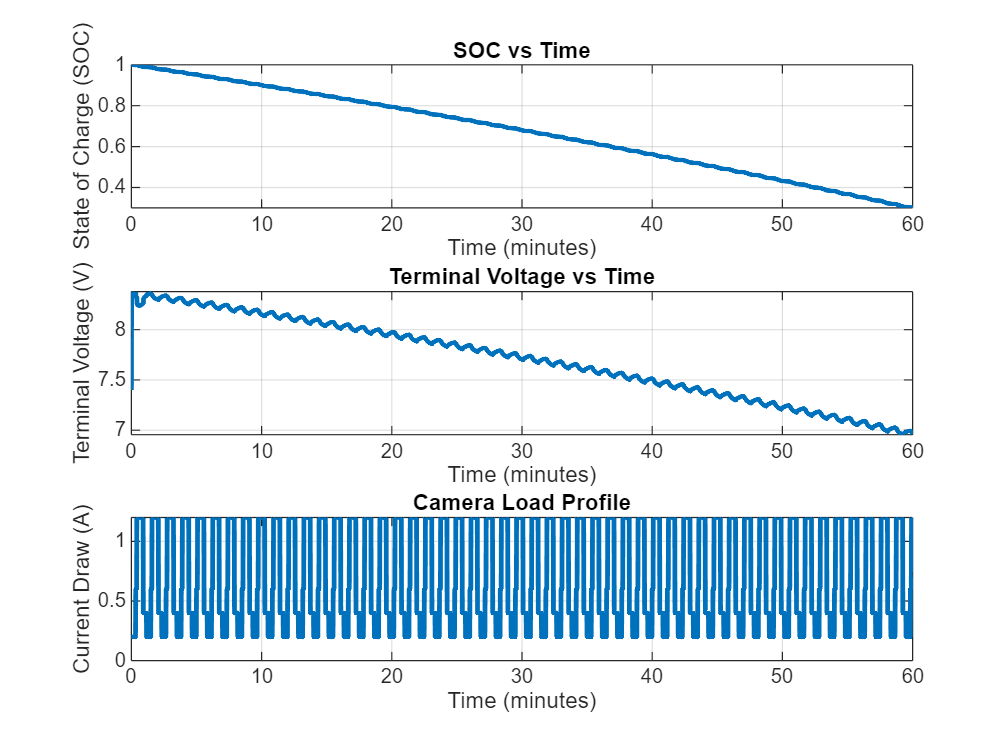

% Parameter variables
Nominal_Voltage = 7.4;
Battery_Capacity = 1.2;
Thevenin_Internal_Resistance = 0.1;    
Thevenin_Dynamic_Resistance = 0.05;   
Dynamic_Capacitance = 200;  
Thermal_Mass = 500;   
Heat_Generation_Coefficient = 5;   
Cooling_Rate = 0.01;
Arrhenius_Beta =10;

% Setting up a 1-hour time simulation
Step = 1;       
Ending_Time = 3600;     
t = 0 : Step : Ending_Time;

% Create all the arrays to add to and plot later
SOC = zeros(size(t));
V = zeros(size(t));
Voc = zeros(size(t));
Vrc = zeros(size(t));
T = zeros(size(t)); 
SOC(1)= 1;
Vrc(1) = 0;
V(1) = 7.4;
T(1) = 25;

% Idle (0.2A for 20s) --> Autofocus & exposure (0.6A for 5s) --> 4K Video
% --> recording (1.2A for 30s) --> Playback (0.4A for 15s)

Photography_Session = [ repmat(0.2, 1, 20), repmat(0.6, 1, 5), repmat(1.2, 1, 30), ...   
    repmat(0.4, 1, 15)];

% Repeat this current usage until it reaches 3600s

Current_Usage = repmat(Photography_Session, 1, ceil(length(t)/length(Photography_Session)));
Current_Usage = Current_Usage(1:length(t));

%Trim any values over the 3600s limit

SOC_curve = linspace(1, 0, 11);  
OCV_curve = [8.4 8.2 8.0 7.8 7.6 7.4 7.2 7.0 6.8 6.6 6.0]; 



for i = 2:length(t)
    SOC(i) = SOC(i-1) - ((Current_Usage(i-1)*Step) / (Battery_Capacity *3600));
    SOC(i) = max(SOC(i), 0);
    
    Voc(i) = interp1(SOC_curve, OCV_curve, SOC(i), 'pchip', 'extrap'); 
    
    Alpha = exp(-Step/(Thevenin_Dynamic_Resistance*Dynamic_Capacitance));
    Vrc(i) = Alpha*Vrc(i-1)+(1-Alpha)*Current_Usage(i-1)*Thevenin_Dynamic_Resistance;
    

    V(i) = Voc(i) - Current_Usage(i-1) * Thevenin_Internal_Resistance - Vrc(i);

    %Modelling the slight battery degradation  over time

    Battery_Capacity = Battery_Capacity * (0.9999);  

    %Modelling the heat increase
    Heat_Generated = Heat_Generation_Coefficient * Current_Usage(i-1)^2;
    T(i) = T(i-1) + (Heat_Generated - Cooling_Rate * (T(i-1) - 25)) * Step / Thermal_Mass;
    Thevenin_Internal_Resistance = Thevenin_Internal_Resistance * exp((25 - T(i)) / Arrhenius_Beta);

end

% Plots
figure;

subplot(3,1,1)
plot(t/60, SOC, 'LineWidth', 2);
xlabel('Time (minutes)'); ylabel('State of Charge (SOC)');
title('SOC vs Time'); grid on;

subplot(3,1,2)
plot(t/60, V, 'LineWidth', 2);
xlabel('Time (minutes)'); ylabel('Terminal Voltage (V)');
title('Terminal Voltage vs Time'); grid on;

subplot(3,1,3)
plot(t/60, Current_Usage, 'LineWidth', 2);
xlabel('Time (minutes)'); ylabel('Current Draw (A)');
title('Camera Load Profile'); grid on;

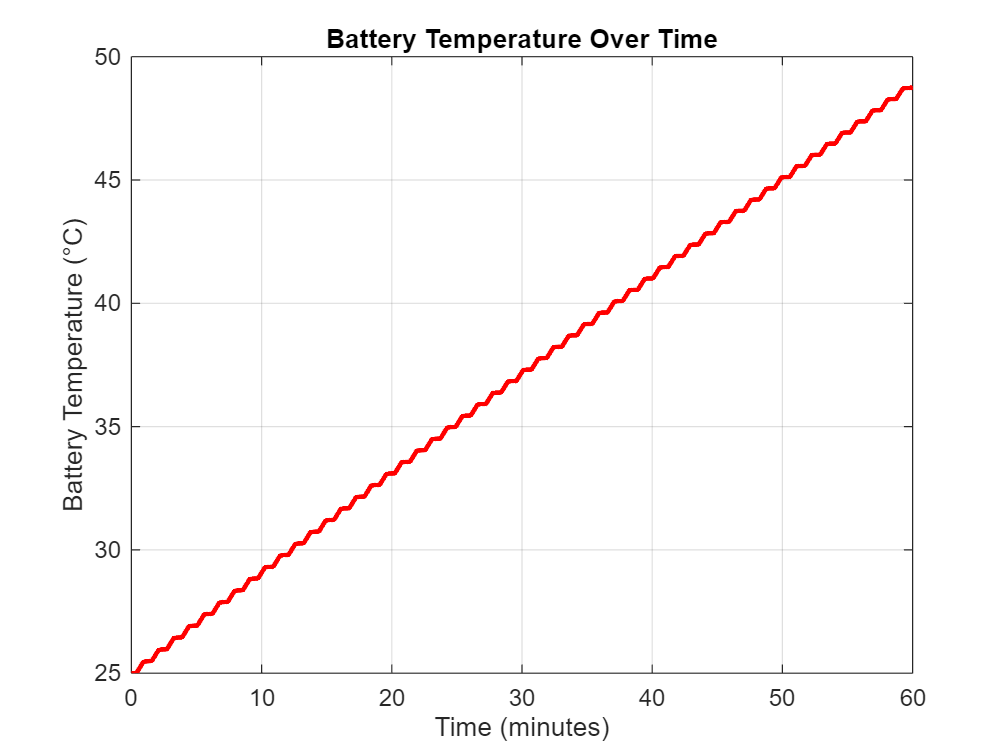


figure;
plot(t/60, T, 'r', 'LineWidth', 2);
xlabel('Time (minutes)');
ylabel('Battery Temperature (°C)');
title('Battery Temperature Over Time');
grid on;